# Structure Arrays

## Create Scalar Structure

First, create a structure named `patient` that has fields storing data about a patient. The diagram shows how the structure stores data. A structure like `patient` is also referred to as a *scalar structure* because the variable stores one structure.

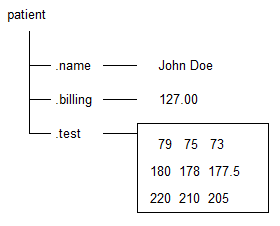

Use dot notation to add the fields `name`, `billing`, and `test`, assigning data to each field. In this example, the syntax `patient.name` creates both the structure and its first field. The commands that follow add more fields.

patient.name = 'John Doe';
patient.billing = 127;
patient.test = [79 75 73; 180 178 177.5; 220 210 205]

## Access Values in Fields

After you create a field, you can keep using dot notation to access and change the value it stores.

For example, change the value of the `billing` field.

patient.billing = 512.00

With dot notation, you also can access the value of any field. For example, make a bar chart of the values in `patient.test`. Add a title with the text in `patient.name`. If a field stores an array, then this syntax returns the whole array.

bar(patient.test)
title("Test Results for " + patient.name)

To access part of an array stored in a field, add indices that are appropriate for the size and type of the array. For example, create a bar chart of the data in one column of `patient.test`.

bar(patient.test(:,1))

## Index into Nonscalar Structure Array

Structure arrays can be nonscalar. You can create a structure array having any size, as long as each structure in the array has the same fields.

For example, add a second structure to `patients` having data about a second patient. Also, assign the original value of `127` to the `billing` field of the first structure. Since the array now has two structures, you must access the first structure by indexing, as in `patient(1).billing = 127`.

patient(2).name = 'Ann Lane';
patient(2).billing = 28.50;
patient(2).test = [68 70 68; 118 118 119; 172 170 169];
patient(1).billing = 127

As a result, `patient` is a 1-by-2 structure array with contents shown in the diagram.

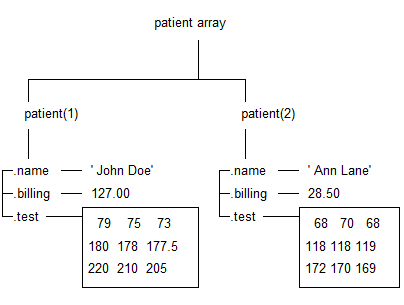

Each patient record in the array is a structure of class `struct`. An array of structures is sometimes referred to as a *struct array*. However, the terms *struct array* and *structure array* mean the same thing. Like other MATLAB® arrays, a structure array can have any dimensions.

A structure array has the following properties:

- All structures in the array have the same number of fields.

- All structures have the same field names.

- Fields of the same name in different structures can contain different types or sizes of data.

If you add a new structure to the array without specifying all of its fields, then the unspecified fields contain empty arrays.

patient(3).name = 'New Name';
patient(3)

To index into a structure array, use array indexing. For example, `patient(2)` returns the second structure.

patient(2)

To access a field, use array indexing and dot notation. For example, return the value of the `billing` field for the second patient.

patient(2).billing

You also can index into an array stored by a field. Create a bar chart displaying only the first two columns of `patient(2).test`.

bar(patient(2).test(:,[1 2]))

*Copyright 2012-2020 The MathWorks, Inc.*